## Practice 1 - **Least Squares in Line Fitting**

Coarse Name: **AIAA 3225 - Learning and Optimization for Artificial**

- **Instructor 1:** Prof. Xin Wang (felixxinwang@hkust-gz.edu.cn), W2-503

- **Instructor 2:** Prof. Zijun Gong (gongzijun@hkust-gz.edu.cn), W4-617

- **Teaching assistant 1:** Keming He, khe827@connect.hkust-gz.edu.cn

- **Teaching assistant 2:** Qinglin Zou, qzou171@connect.hkust-gz.edu.cn

### Objective

The first goal of this practice is to act as a 'Hello, World!' introduction to AIAA 3225 and to ensure your PC's coding setup is working correctly.

The second goal of this practice is to solve a fundamental **Least Squares** problem using two different methods:

- A **numerical solution** using the convex optimization tool **CVX**.

- The **analytical solution** derived from setting the gradient of the cost function to zero.

This will help you understand the connection between classical statistical methods and modern convex optimization.

### Problem

We are given a set of $n$ data points $$(x_i, y_i)$$. Our model assumes a linear relationship:


$$$y_i =\theta_1 x_i + \theta_2$$$


We now give the code to generate data and simply draw a figure

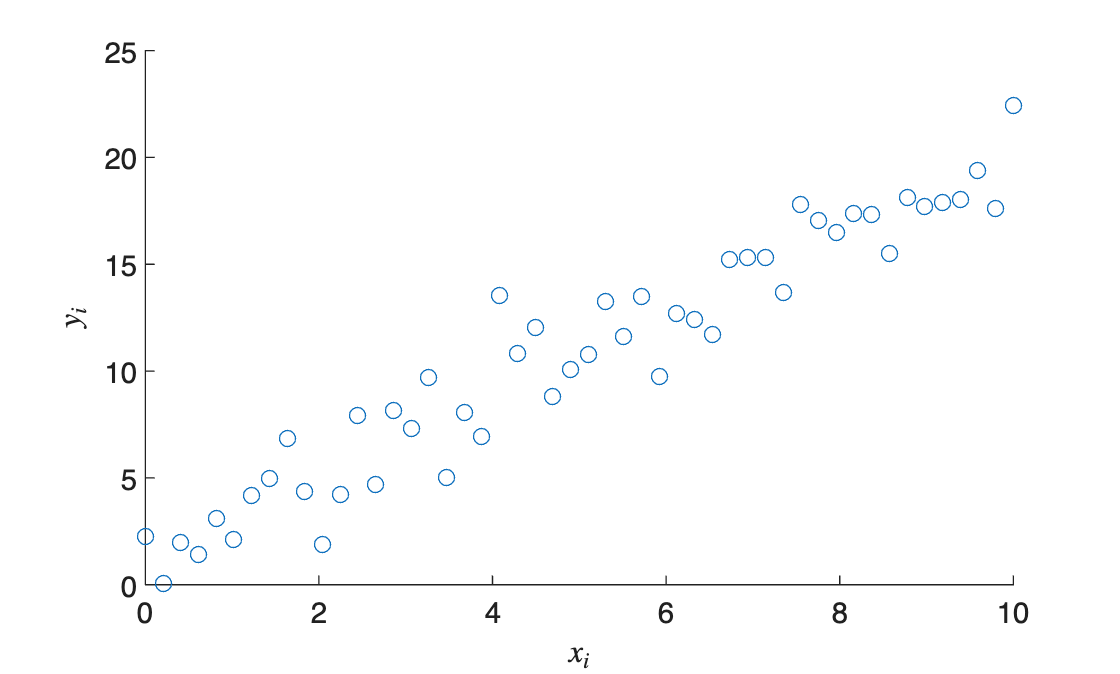

clear; close all; clc % First, we clear unnecessary data, close the previous figures, and clear the command line window.

n = 50; % Number of data points

% True line parameters: y = 2x + 1
x = linspace(0, 10, n)';
true_slope = 2;
true_intercept = 1;
y_true = true_slope * x + true_intercept;

% Generate noisy observations
noise_std = 1.5; % Standard deviation of Gaussian noise
y = y_true + noise_std * randn(n, 1); 

figure
scatter(x,y);
xlabel('$x_i$','Interpreter','latex');
ylabel('$y_i$','Interpreter','latex');

We want to find the parameters $$\mathbf{\theta }= [\theta_1, \theta_2]^T$$ (slope and intercept) that make our model's predictions as close as possible to the observed data. We measure "closeness" using the sum of squared errors:


$$\underset{\theta_1, \theta_2}{\text{min}} \quad \sum_{i=1}^{n} ( \theta_1 x_i + \theta_2 - y_i )^2$$


This can be written more compactly in vector form, which makes it easier for us to recognize the least squares form we saw in class


$$\underset{\mathbf{\theta}}{\text{min}} \quad \| \mathbf{X} \mathbf{\theta} - \mathbf{y} \|_2^2$$


where matrix $\mathbf{X}$ and the observation vector $\mathbf{y}$ are given as:

$\mathbf{X}=\left\lbrack \begin{array}{cc}
x_1  & 1\\
x_2  & 1\\
\vdots  & \vdots \\
x_n  & 1
\end{array}\right\rbrack ,\mathbf{y}=\left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
\vdots \\
y_n 
\end{array}\right\rbrack ,\;$$$\mathbf{\theta }= $$\left\lbrack \begin{array}{c}
\theta_1 \\
\theta_2 
\end{array}\right\rbrack$.

### Coding Practice 1: Analytical Solution (Normal Equations) of Least Squares Problem

By taking the gradient of the objective function $$\| \mathbf{X}\mathbf{\theta} - \mathbf{y} \|_2^2$$ and setting it to zero, we derive the famous normal equations:


$$\nabla_{\mathbf{\theta}} \| \mathbf{X}\mathbf{\theta} - \mathbf{y} \|_2^2 = 0 \quad \Rightarrow \quad \mathbf{X}^T \mathbf{X} \mathbf{\theta} = \mathbf{X}^T \mathbf{y}$$


Assuming $\mathbf{X}^T \mathbf{X}$ is invertible, the optimal parameter vector has a closed-form solution:


$$\mathbf{\theta}^* = (\mathbf{X}^T \mathbf{X})^{-1} \mathbf{X}^T \mathbf{y}$$


Let's implement this in MATLAB. Hope you haven't forgotten how to use MATLAB😄.

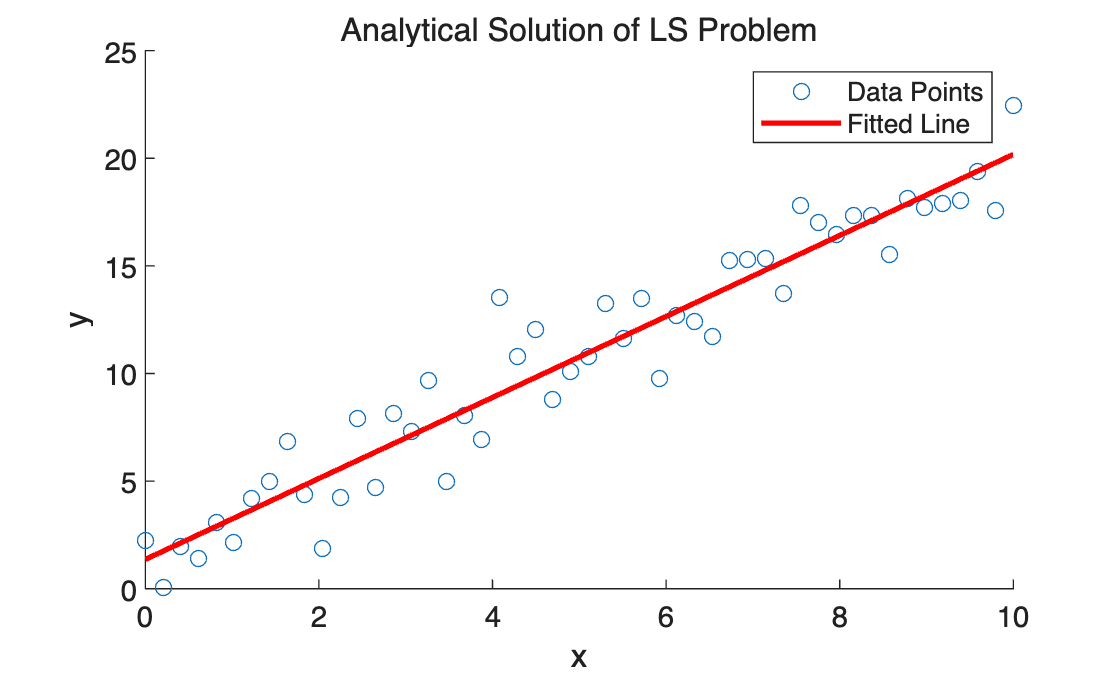


% Construct matrix X = [x, 1]
X = [x, ones(n, 1)];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%     Task 1    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Calculte theta_analytic,slope_analytic and intercept_analytic
% Hint: Solve the normal equations: theta = (X' * X) \ (X' * y)
% Please note the difference between ' and .'
theta_analytic = (X.' * X) \ (X.' * y);   % solves normal equations

slope_analytic = theta_analytic(1);      % 对应 x 的系数（斜率）
intercept_analytic = theta_analytic(2);  % 常数项（截距）

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure
scatter(x, y); hold on;
plot(x, slope_analytic * x + intercept_analytic, 'r', 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('Analytical Solution of LS Problem');
legend('Data Points', 'Fitted Line');
hold off;

### Coding Practice 2: Numerical Solution of Least Squares Problem Using CVX 

Now, we will solve the same problem using CVX. Instead of using the derived formula, we describe the optimization problem directly in a natural, human-readable syntax. CVX then automatically transforms this problem into a standard form that a solver can handle.

The problem to solve using CVX:


$$\underset{\mathbf{\theta}}{\text{min}} \quad \| \mathbf{X} \mathbf{\theta} - \mathbf{y} \|_2$$


*(Note: Minimizing the L2 norm *`norm(.)`* is equivalent to minimizing the squared norm *`norm(.)^2`*, as CVX is smart enough to handle this.)*

X = [x, ones(n, 1)]; 


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%     Task 2    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Solve this problem by cvx

cvx_begin
variable: theta = [theta1; theta2]   % Declare optimization variable: theta = [theta1; theta2]

索引超出数组范围。

出错 variable (第 76 行)
xname = name{1};
^^^^^^^^^^^^^^^^

minimize     % Fill the optimazation objective

cvx_end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
slope_cvx = theta(1);
intercept_cvx = theta(2);

figure
scatter(x, y); hold on;
plot(x, slope_cvx * x + intercept_cvx, 'r', 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('CVX Solution of LS Problem');
legend('Data Points', 'Fitted Line');
hold off;


% % Here is another way
% cvx_begin
%     variables a b
%     minimize( sum_square( y - (a * x + b) ) )
% cvx_end
% slope_cvx = a;
% intercept_cvx = b;
% 
% 
% figure
% scatter(x, y); hold on;
% plot(x, slope_cvx * x + intercept_cvx, 'r', 'LineWidth', 2);
% xlabel('x');
% ylabel('y');
% title('CVX Solution of LS Problem');
% legend('Data Points', 'Fitted Line');
% hold off;